Question 6

part a

%% create obstacle field
close all
clear all
waypoints=300;
N=101;
OBST = [20,30;60,40;70,85];
epsilon = [25; 20; 30];

obs_cost = double(zeros(N));
for i=1:size(OBST,1)

    t = zeros(N);
    t(OBST(i,1),OBST(i,2)) = 1; %point obstacles
    
    t_cost = double(bwdist(t));
    t_cost(t_cost>epsilon(i))=epsilon(i);
    t_cost = 1/(2*epsilon(i))*(t_cost-epsilon(i)).^2;
    
    obs_cost = obs_cost + t_cost(1:N, 1:N);
end

figure(1)
imagesc(obs_cost')
% obstacle cost gradient
gx = diff(double(obs_cost),1,1);
gy = diff(double(obs_cost),1,2);
hold on


figure(1);
surface(1:N,1:N,double(obs_cost'));
xlabel('X')
hold on;

%% initial path
%world params
SX = 10; % START
SY = 10;
GX = 90; % GOAL
GY = 90;


traj = zeros(2,waypoints);
traj(1,1)=SX;
traj(2,1)=SY;
dist_x = GX-SX;
dist_y = GY-SY;
for i=2:waypoints
    traj(1,i)=traj(1,i-1)+dist_x/(waypoints-1);
    traj(2,i)=traj(2,i-1)+dist_y/(waypoints-1);
end

path_init = traj';
tt=size(path_init,1);
path_init_values = zeros(size(path_init,1),1);
for i=1:tt
    path_init_values(i)=obs_cost(floor(path_init(i,1)),floor(path_init(i,2)));
end
plot3(path_init(:,1),path_init(:,2),path_init_values,'.r','MarkerSize',20);
hold on

path = path_init;


%% Optimize it...
% your code comes here

%% Optimize it...  (Part a: obstacle cost only)
scale = 0.1;
max_iter = 200;

for iter = 1:max_iter
    for i = 2:tt-1
        x = path(i,1); y = path(i,2);
        % skip if out of grid bounds
        if x < 1 || x > N-1 || y < 1 || y > N-1
            continue;
        end
        % bilinear interpolation for gx, gy
        interp_x1 = (x - fix(x))*(gx(fix(x)+1, fix(y)) - gx(fix(x), fix(y))) + gx(fix(x), fix(y));
        interp_x2 = (x - fix(x))*(gx(fix(x)+1, fix(y)+1) - gx(fix(x), fix(y)+1)) + gx(fix(x), fix(y)+1);
        grad_x = (y - fix(y))*(interp_x2 - interp_x1) + interp_x1;

        interp_y1 = (x - fix(x))*(gy(fix(x)+1, fix(y)) - gy(fix(x), fix(y))) + gy(fix(x), fix(y));
        interp_y2 = (x - fix(x))*(gy(fix(x)+1, fix(y)+1) - gy(fix(x), fix(y)+1)) + gy(fix(x), fix(y)+1);
        grad_y = (y - fix(y))*(interp_y2 - interp_y1) + interp_y1;

        % update path point
        path(i,1) = x - scale * grad_x;
        path(i,2) = y - scale * grad_y;
    end
    % optionally visualize every few iterations
    if mod(iter,50)==0
        fprintf('Iteration %d complete\n', iter);
    end
end

Iteration 50 complete
Iteration 100 complete
Iteration 150 complete
Iteration 200 complete


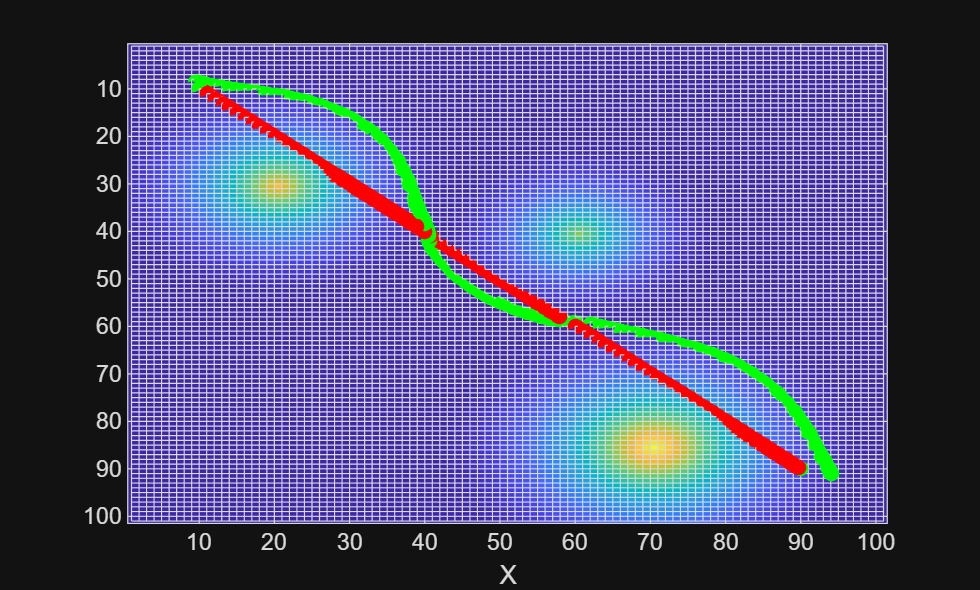




%% plot the trajectories
path_values = zeros(tt,1);
for i=1:tt
    path_values(i)=obs_cost(floor(path(i,1)),floor(path(i,2)));
end
figure(1)
hold on;
plot3(path(:,1),path(:,2),path_values,'.g','MarkerSize',20);

hold off;

Part B

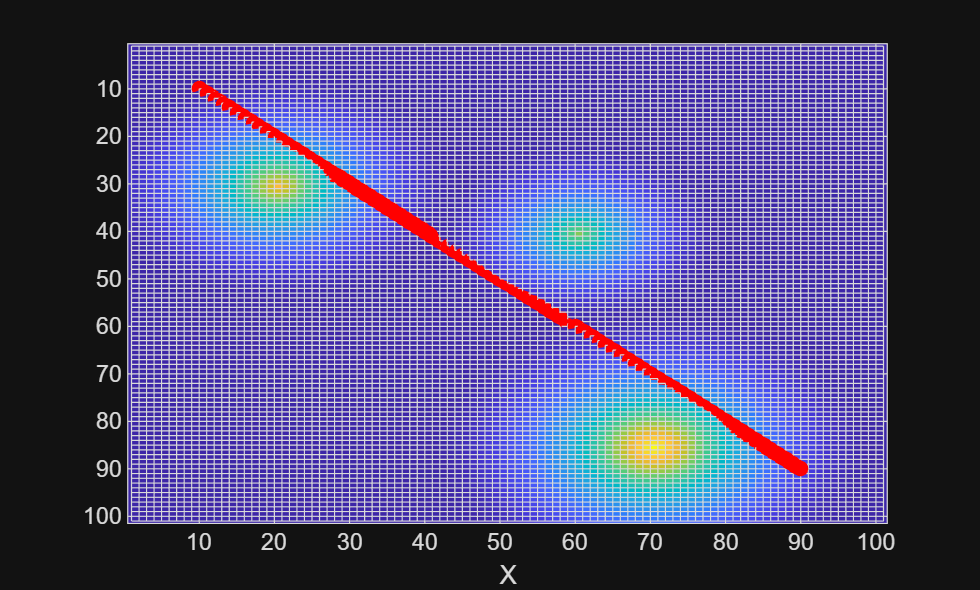

%% create obstacle field

clear all
waypoints=300;
N=101;
OBST = [20,30;60,40;70,85];
epsilon = [25; 20; 30];

obs_cost = double(zeros(N));
for i=1:size(OBST,1)

    t = zeros(N);
    t(OBST(i,1),OBST(i,2)) = 1; %point obstacles
    
    t_cost = double(bwdist(t));
    t_cost(t_cost>epsilon(i))=epsilon(i);
    t_cost = 1/(2*epsilon(i))*(t_cost-epsilon(i)).^2;
    
    obs_cost = obs_cost + t_cost(1:N, 1:N);
end

figure(1)
imagesc(obs_cost')
% obstacle cost gradient
gx = diff(double(obs_cost),1,1);
gy = diff(double(obs_cost),1,2);
hold on


figure(1);
surface(1:N,1:N,double(obs_cost'));
xlabel('X')
hold on;

%% initial path
%world params
SX = 10; % START
SY = 10;
GX = 90; % GOAL
GY = 90;


traj = zeros(2,waypoints);
traj(1,1)=SX;
traj(2,1)=SY;
dist_x = GX-SX;
dist_y = GY-SY;
for i=2:waypoints
    traj(1,i)=traj(1,i-1)+dist_x/(waypoints-1);
    traj(2,i)=traj(2,i-1)+dist_y/(waypoints-1);
end

path_init = traj';
tt=size(path_init,1);
path_init_values = zeros(size(path_init,1),1);
for i=1:tt
    path_init_values(i)=obs_cost(floor(path_init(i,1)),floor(path_init(i,2)));
end
plot3(path_init(:,1),path_init(:,2),path_init_values,'.r','MarkerSize',20);
hold on

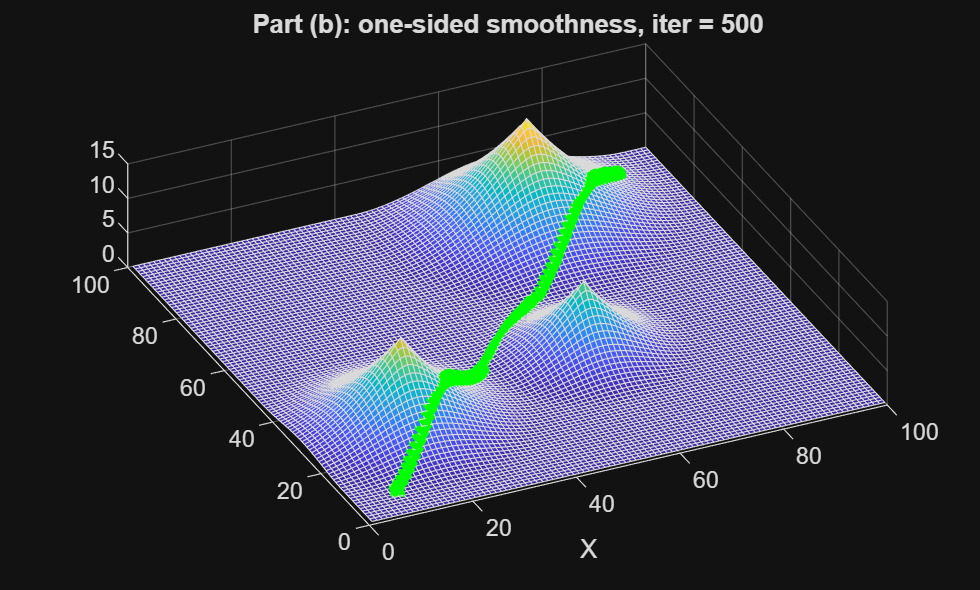


path = path_init;


%% Optimize it...
% your code comes here

path_b = path_init;

w_obs = 0.8;    % weight for obstacle cost gradient
w_smo = 4.0;    % weight for smoothness (xi - xi-1)
alpha = 0.1;    % step-size scaling
max_iter = 500;

for iter = 1:max_iter

    for i = 2:tt-1
        x = path_b(i,1); y = path_b(i,2);

        if x < 1 || x > N-1 || y < 1 || y > N-1
            continue;
        end

        ix = fix(x); iy = fix(y);
        interp_x1 = (x - ix) * (gx(ix+1, iy)   - gx(ix, iy))   + gx(ix, iy);
        interp_x2 = (x - ix) * (gx(ix+1, iy+1) - gx(ix, iy+1)) + gx(ix, iy+1);
        grad_x = (y - iy) * (interp_x2 - interp_x1) + interp_x1;

        interp_y1 = (x - ix) * (gy(ix+1, iy)   - gy(ix, iy))   + gy(ix, iy);
        interp_y2 = (x - ix) * (gy(ix+1, iy+1) - gy(ix, iy+1)) + gy(ix, iy+1);
        grad_y = (y - iy) * (interp_y2 - interp_y1) + interp_y1;

        grad_obs = [grad_x, grad_y];  

        grad_smooth = (path_b(i,:) - path_b(i-1,:)); 

        total_step = - w_obs * grad_obs - w_smo * grad_smooth;

        path_b(i,:) = path_b(i,:) + alpha * total_step;
    end

    % quick snapshots
    if iter == 100 || iter == 200 || iter == 500
        pv = zeros(tt,1);
        for k = 1:tt
            pv(k) = obs_cost(floor(path_b(k,1)), floor(path_b(k,2)));
        end
        figure(10); if iter==100, clf; end
        surf(1:N,1:N,double(obs_cost')), view(-25,70); hold on;
        xlabel('X'); xlim([0 100]); ylim([0 100]);
        plot3(path_init(:,1), path_init(:,2), path_init_values, '.r', 'MarkerSize', 12);
        plot3(path_b(:,1),   path_b(:,2),   pv,                 '.g', 'MarkerSize', 18);
        title(sprintf('Part (b): one-sided smoothness, iter = %d', iter));
        hold off;
        drawnow;
    end
end



%% plot the trajectories
path_values = zeros(tt,1);
for i=1:tt
    path_values(i)=obs_cost(floor(path(i,1)),floor(path(i,2)));
end
figure(1)
hold on;
plot3(path(:,1),path(:,2),path_values,'.g','MarkerSize',20);

hold off;

Part C

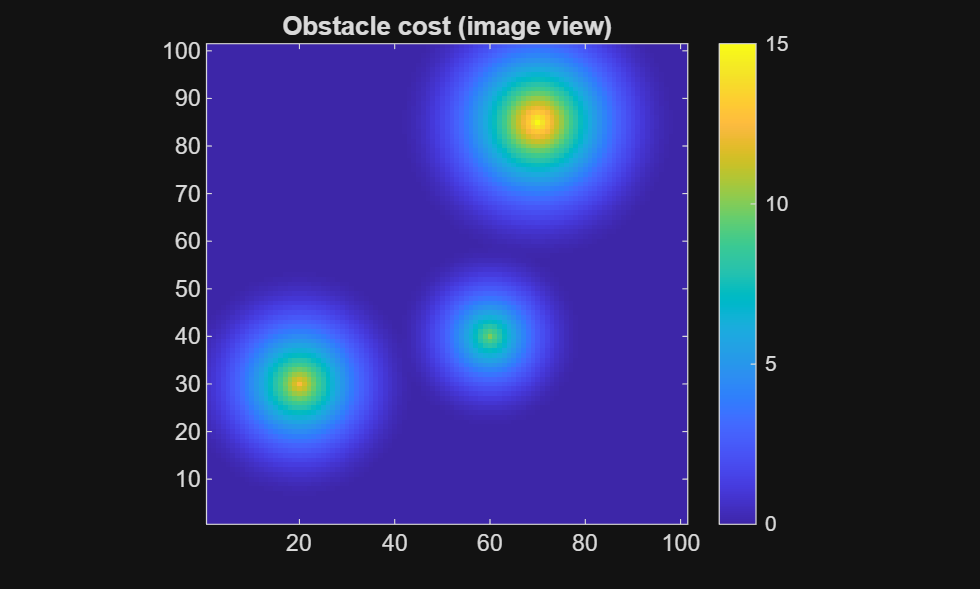

%% create obstacle field
clear all;

waypoints = 300;
N = 101;
OBST    = [20,30; 60,40; 70,85];
epsilon = [25;     20;    30];

obs_cost = double(zeros(N));
for i = 1:size(OBST,1)
    t = zeros(N);
    t(OBST(i,1), OBST(i,2)) = 1;          % point obstacle
    t_cost = double(bwdist(t));
    t_cost(t_cost > epsilon(i)) = epsilon(i);
    t_cost = 1/(2*epsilon(i)) * (t_cost - epsilon(i)).^2;
    obs_cost = obs_cost + t_cost(1:N, 1:N);
end

figure(1); clf;
imagesc(obs_cost'); axis image xy; colormap parula; colorbar;
title('Obstacle cost (image view)'); hold on;

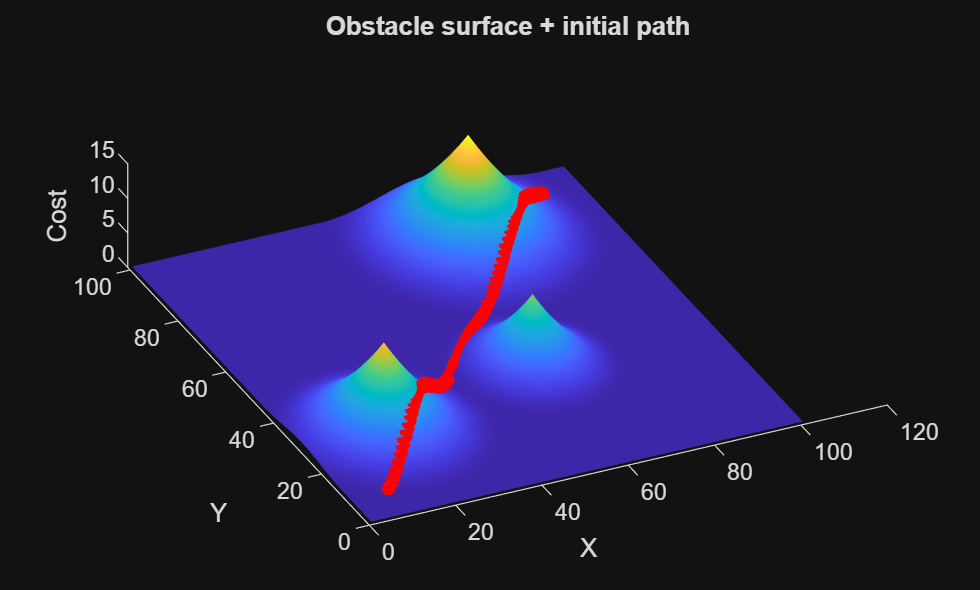


% Discrete gradients (two flavors)
gx = diff(double(obs_cost),1,1);   % (N-1) x N
gy = diff(double(obs_cost),1,2);   % N x (N-1)
[FX,FY] = gradient(obs_cost);      % N x N (centered finite-diff)

figure(2); clf;
surface(1:N,1:N,double(obs_cost')); shading interp; view(-25,70);
xlabel('X'); ylabel('Y'); zlabel('Cost'); title('Obstacle surface'); hold on;

%% initial path (straight line)
SX = 10; SY = 10;    % START
GX = 90; GY = 90;    % GOAL

traj = zeros(2,waypoints);
traj(1,1) = SX; traj(2,1) = SY;
dist_x = GX - SX; dist_y = GY - SY;
for i = 2:waypoints
    traj(1,i) = traj(1,i-1) + dist_x/(waypoints-1);
    traj(2,i) = traj(2,i-1) + dist_y/(waypoints-1);
end
path_init = traj.';              % (tt x 2)
tt = size(path_init,1);

path_init_values = zeros(tt,1);
for i = 1:tt
    % clamp to grid just in case
    xi = min(max(floor(path_init(i,1)),1),N);
    yi = min(max(floor(path_init(i,2)),1),N);
    path_init_values(i) = obs_cost(xi, yi);
end

plot3(path_init(:,1), path_init(:,2), path_init_values, '.r', 'MarkerSize', 18);
title('Obstacle surface + initial path');

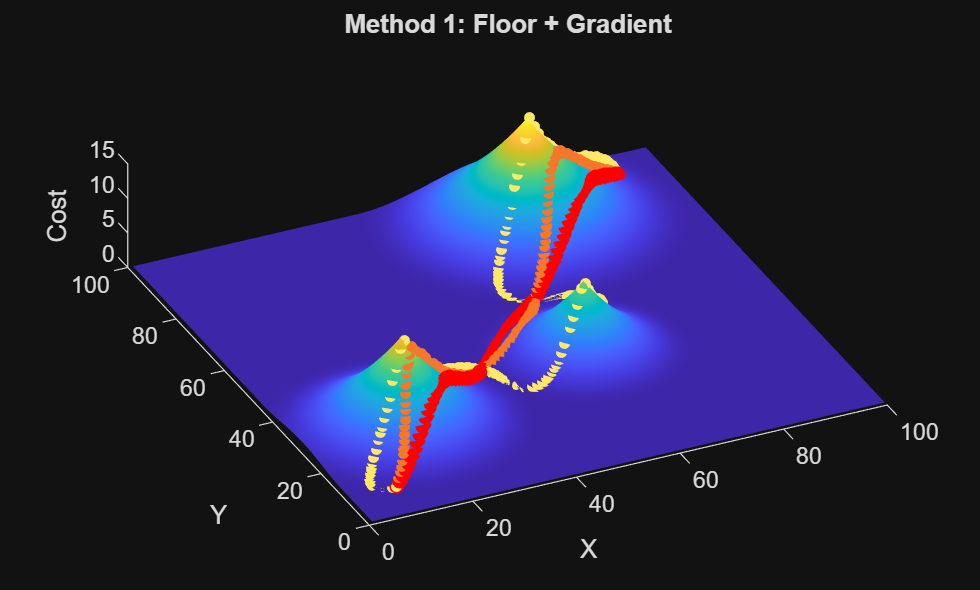


%% ---------- Q6(c) weights & step ----------
w_obs = 0.8;         % obstacle gradient weight
w_smo = 4.0;         % smoothness weight
alpha = 0.1;         % step size
max_iter = 5000;
snap_iters = [100, 5000];   % required snapshots

%% ================== Method 1: Floor + Gradient ==================
% Uses integer (floor) indexing into FX, FY; two-sided smoothness:
% grad_smooth(i) = -x_{i-1} + 2 x_i - x_{i+1}  (per assignment)
path1 = path_init;

figure(3); clf;
surface(1:N,1:N,double(obs_cost')); shading interp; view(-25,70);
xlabel('X'); ylabel('Y'); zlabel('Cost');
title('Method 1: Floor + Gradient'); xlim([0 100]); ylim([0 100]); hold on;
plot3(path_init(:,1), path_init(:,2), path_init_values, '.r','MarkerSize',18);

for k = 1:max_iter
    pre_path = path1; % keep previous path for smoothness term
    for i = 2:tt-1
        % clamp indices to valid grid (1..N)
        xi = min(max(floor(path1(i,1)),1),N);
        yi = min(max(floor(path1(i,2)),1),N);

        % obstacle gradient (uphill) from FX,FY at integer cell
        grad_obs = [FX(xi, yi), FY(xi, yi)];

        % two-sided smoothness
        grad_smooth = -pre_path(i-1,:) + 2*pre_path(i,:) - pre_path(i+1,:);

        % total step: negative of weighted gradients
        total_step  = - w_obs*grad_obs - w_smo*grad_smooth;
        path1(i,:)  = path1(i,:) + alpha * total_step;
    end

    if ismember(k, snap_iters)
        pv = zeros(tt,1);
        for j = 1:tt
            xi = min(max(floor(path1(j,1)),1),N);
            yi = min(max(floor(path1(j,2)),1),N);
            pv(j) = obs_cost(xi, yi);
        end
        plot3(path1(:,1), path1(:,2), pv, '.','MarkerSize',14);
        drawnow;
    end
end

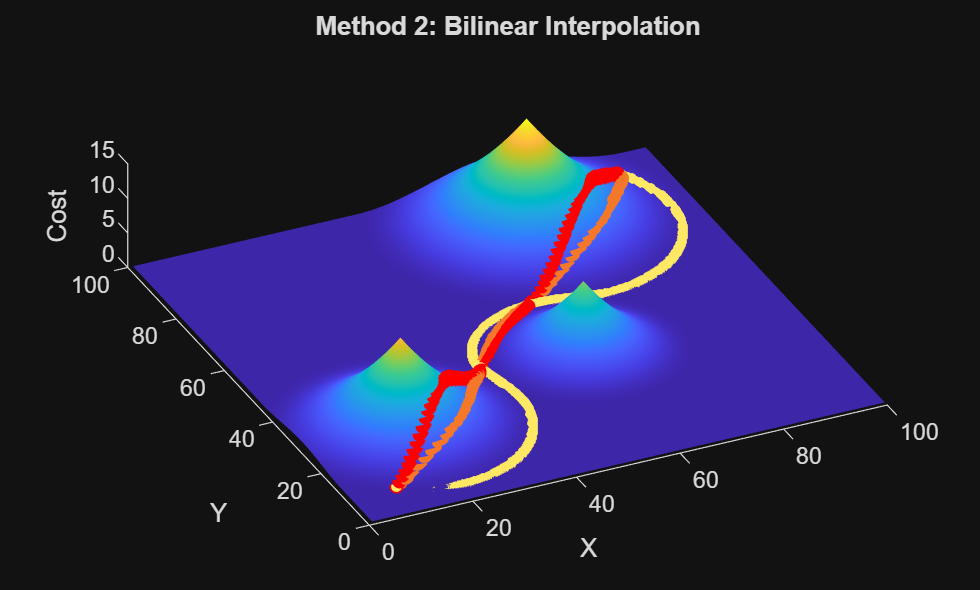


%% ================== Method 2: Bilinear Interpolation + pre_path ==================
% Interpolates gx, gy (the forward diffs) bilinearly; uses same two-sided smoothness.
path2 = path_init;

figure(4); clf;
surface(1:N,1:N,double(obs_cost')); shading interp; view(-25,70);
xlabel('X'); ylabel('Y'); zlabel('Cost');
title('Method 2: Bilinear Interpolation'); xlim([0 100]); ylim([0 100]); hold on;
plot3(path_init(:,1), path_init(:,2), path_init_values, '.r','MarkerSize',18);

for k = 1:max_iter
    pre_path2 = path2;

    for i = 2:tt-1
        x = path2(i,1);  y = path2(i,2);

        % keep interior points inside [1, N-1] so (ix+1, iy+1) are valid
        x = min(max(x, 1), N-1);
        y = min(max(y, 1), N-1);
        ix = fix(x);    iy = fix(y);

        % ---- bilinear interpolation for gx (size (N-1) x N) ----
        % along x first (between ix and ix+1), then y between iy and iy+1
        interp_x1 = (x - ix)*(gx(ix+1, iy)   - gx(ix, iy))   + gx(ix, iy);
        interp_x2 = (x - ix)*(gx(ix+1, iy+1) - gx(ix, iy+1)) + gx(ix, iy+1);
        grad_x    = (y - iy)*(interp_x2 - interp_x1) + interp_x1;

        % ---- bilinear interpolation for gy (size N x (N-1)) ----
        interp_y1 = (x - ix)*(gy(ix+1, iy)   - gy(ix, iy))   + gy(ix, iy);
        interp_y2 = (x - ix)*(gy(ix+1, iy+1) - gy(ix, iy+1)) + gy(ix, iy+1);
        grad_y    = (y - iy)*(interp_y2 - interp_y1) + interp_y1;

        grad_obs = [grad_x, grad_y];                   % uphill
        grad_smooth = -pre_path2(i-1,:) + 2*pre_path2(i,:) - pre_path2(i+1,:);

        total_step = - w_obs*grad_obs - w_smo*grad_smooth;
        path2(i,:) = path2(i,:) + alpha * total_step;

        % (optional) keep path inside the grid for display
        path2(i,1) = min(max(path2(i,1), 1), N-1);
        path2(i,2) = min(max(path2(i,2), 1), N-1);
    end

    if ismember(k, snap_iters)
        pv = zeros(tt,1);
        for j = 1:tt
            xi = min(max(floor(path2(j,1)),1),N);
            yi = min(max(floor(path2(j,2)),1),N);
            pv(j) = obs_cost(xi, yi);
        end
        plot3(path2(:,1), path2(:,2), pv, '.','MarkerSize',14);
        drawnow;
    end
end

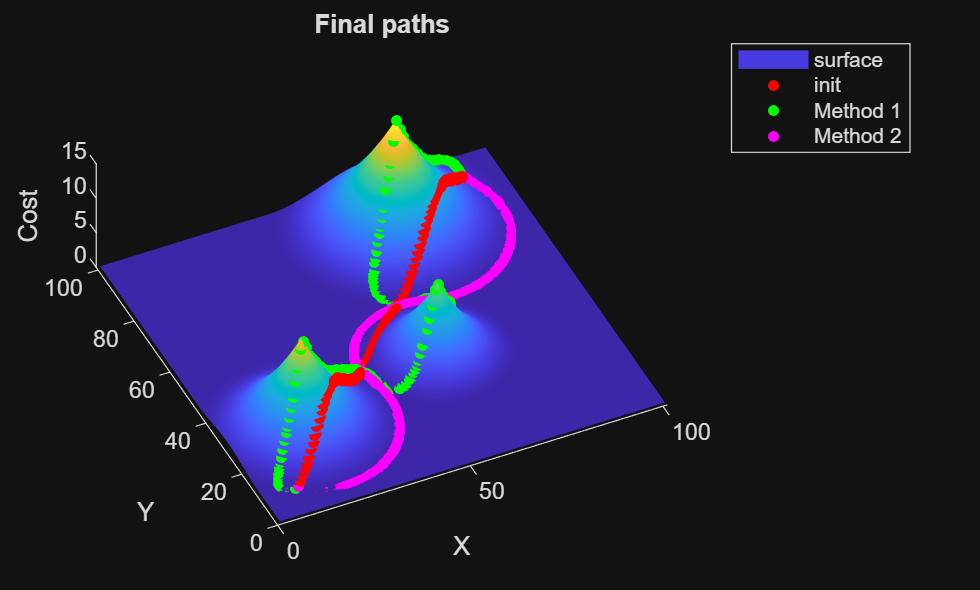


%% (Optional) overlay final 3D trajectories on surface
figure(5); clf;
surface(1:N,1:N,double(obs_cost')); shading interp; view(-25,70);
xlabel('X'); ylabel('Y'); zlabel('Cost'); hold on; title('Final paths');
pv1 = arrayfun(@(k) obs_cost(min(max(floor(path1(k,1)),1),N), min(max(floor(path1(k,2)),1),N)), 1:tt).';
pv2 = arrayfun(@(k) obs_cost(min(max(floor(path2(k,1)),1),N), min(max(floor(path2(k,2)),1),N)), 1:tt).';
plot3(path_init(:,1), path_init(:,2), path_init_values, '.r','MarkerSize',14);
plot3(path1(:,1),     path1(:,2),     pv1,             '.g','MarkerSize',14);
plot3(path2(:,1),     path2(:,2),     pv2,             '.m','MarkerSize',14);
legend('surface','init','Method 1','Method 2'); hold off;

Part D

No—the final path need **not** be the same. With gradient-based optimization on a **non-convex** cost landscape (obstacle costs + smoothness), the algorithm converges to a **local minimum** within the basin of attraction of the chosen initial path. Different starting paths can land in different basins and yield **different locally optimal** (and comparably “good”) paths.

Part E

Increase the obstacle cost influence by enlarging each obstacle’s radius (ε) or increasing its weight (for example, from 0.8 to 1.5), so the path is pushed farther away from high-cost regions.